format long
day1=readtable("EE101_Project2_Data.xlsx",Sheet="11Jan2020",VariableNamingRule="preserve");
date1=day1(:,1);
time=table2array(day1(:,2));
power1=table2array(day1(:,5));
cnv_t=duration(time);
t=linspace(1,24,144)

t =    1.000000000000000   1.160839160839161   1.321678321678322   1.482517482517482   1.643356643356643   1.804195804195804   1.965034965034965   2.125874125874126   2.286713286713287   2.447552447552447   2.608391608391608   2.769230769230769   2.930069930069930   3.090909090909091   3.251748251748252   3.412587412587412   3.573426573426573   3.734265734265734   3.895104895104895   4.055944055944056   4.216783216783217   4.377622377622377   4.538461538461538   4.699300699300699   4.860139860139860   5.020979020979021   5.181818181818182   5.342657342657342   5.503496503496503   5.664335664335664   5.825174825174825   5.986013986013986   6.146853146853147   6.307692307692307   6.468531468531468   6.629370629370629   6.790209790209790   6.951048951048951   7.111888111888112   7.272727272727272   7.433566433566433   7.594405594405594   7.755244755244755   7.916083916083916   8.076923076923077   8.237762237762237   8.398601398601398   8.559440559440560   8.720279720279720   8.88111888111

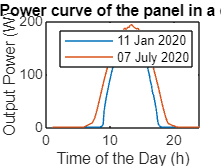

day2=readtable("EE101_Project2_Data.xlsx",Sheet="07July2020",VariableNamingRule="preserve");
date2=day2(:,1);
power2=table2array(day2(:,5));

figure
plot(t,power1)
title("Power curve of the panel in a day")
xlabel("Time of the Day (h)")
ylabel("Output Power (W)")
hold on
plot(t,power2)
legend("11 Jan 2020" ,"07 July 2020")




summer_q2=trapz(cnv_t,power2)/6000

summer_q2 = duration
   00:15:08


winter_q2=trapz(power1)/6000

winter_q2 =    1.088732868508328


winter=(power1/1000)*4878

winter = 1.0e+02 *

  -0.000009856696554
  -0.000008468666532
  -0.000009803619036
  -0.000010147064382
  -0.000012035650374
  -0.000008788287726
  -0.000009957607740
  -0.000010102684338
  -0.000010817867430
  -0.000011191927104


demand_winter=450-winter

demand_winter = 1.0e+02 *

   4.500009856696554
   4.500008468666532
   4.500009803619036
   4.500010147064382
   4.500012035650374
   4.500008788287726
   4.500009957607740
   4.500010102684338
   4.500010817867430
   4.500011191927104


summer=(power2/1000)*4878

summer = 1.0e+02 *

  -0.000004734526801
  -0.000004479481058
  -0.000003987765488
  -0.000004797816412
  -0.000004455194960
  -0.000004648571075
  -0.000004883170680
  -0.000003996972225
  -0.000004353206224
  -0.000004313765155


demand_summer=450-summer

demand_summer = 1.0e+02 *

   4.500004734526801
   4.500004479481058
   4.500003987765488
   4.500004797816412
   4.500004455194960
   4.500004648571075
   4.500004883170680
   4.500003996972225
   4.500004353206224
   4.500004313765155


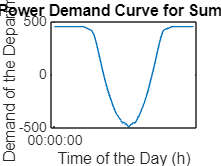

figure
plot(cnv_t,demand_summer)
ylabel("Power Demand of the Department (kW)")
xlabel("Time of the Day (h)")
title("Power Demand Curve for Summer")

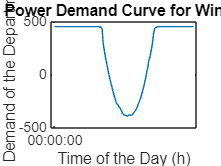


figure
plot(cnv_t,demand_winter)
ylabel("Power Demand of the Department (kW)")
xlabel("Time of the Day (h)")
title("Power Demand Curve for Winter")





%efficiencywin=21.4173151
%efficiencysummer=18.5464833